# **PRACTICE 2. REGRESSION**

## Grado en Ingeniería Informática - Reconocimiento de Patrones

## Fernando M. Quintana Velázquez - Guillermo Bárcena González

# **EXERCISE 1: LINEAR REGRESSION**

**The data in the accompanying table relate heart rate at rest (Y) to kilograms body weight (X).**

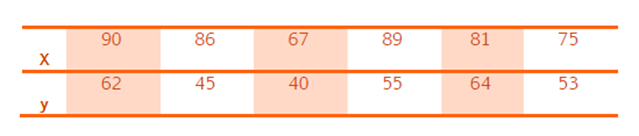

**a) Graph these data. Does exist a linear relationship between body weight and resting heart rate? **

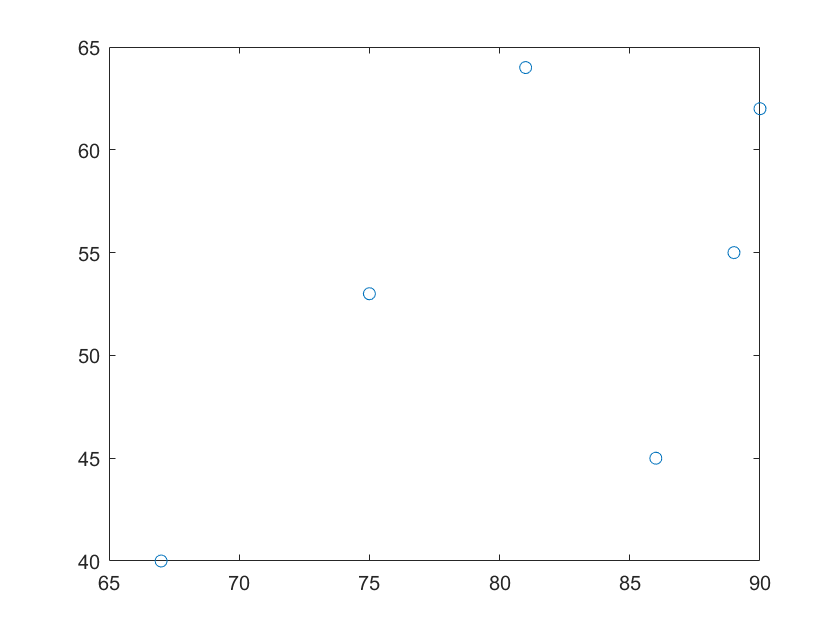

clear all;
close all;
figure (1);
x=[90,86,67,89,81,75];
y=[62,45,40,55,64,53];
plot(x,y,'o');

It looks like there is no big relation

**b) Compute the regression equation for these data. Then, plot the regression line over the graph of the paragraph a. Interpret the estimated regression coefficients.**

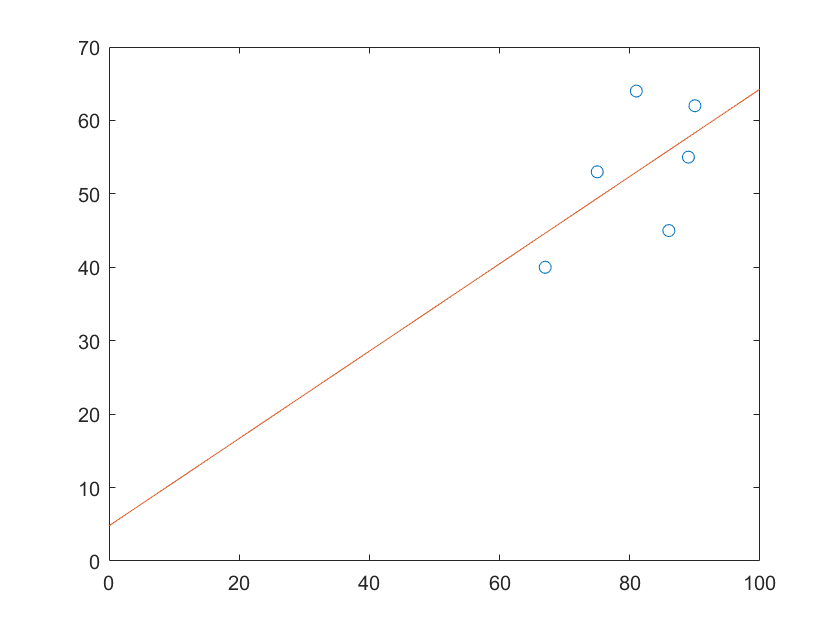

figure(2);
A=[sum(x.*x)   sum(x)
     sum(x)    length(y)]; 
v=[sum(x.*y) sum(y)]';
plot(x,y,'o'); hold on;
sol=A\v; 
a=sol(1);
b = sol(2);
xr=[0:1:100];
yr=a*xr+b;
plot (xr,yr);hold off;

a

a = 0.5947

b

b = 4.7990

**c) Now examine the value on (67, 40) point . If this data point were removed from the data set, what changes would occur in the estimates of a and b coeficients?**

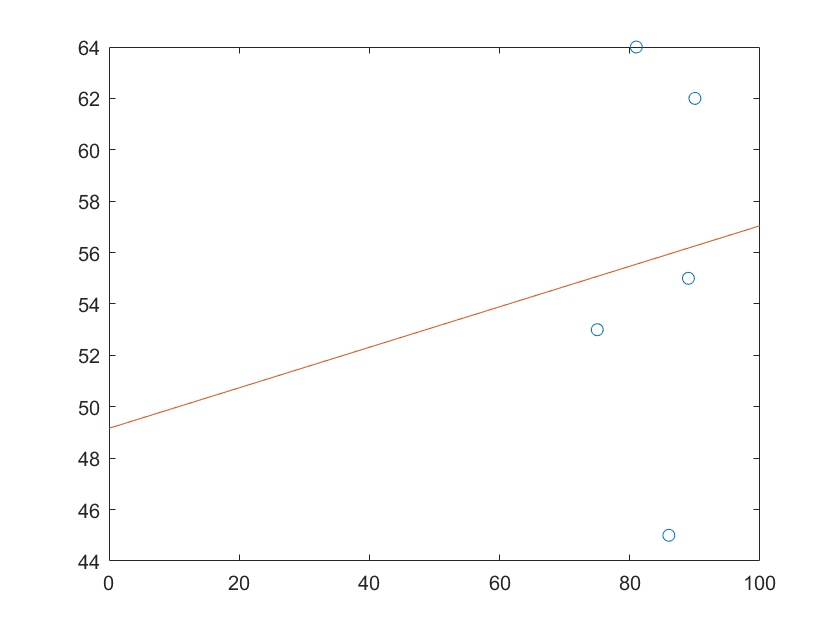

figure(3);
x=[90,86,89,81,75];
y=[62,45,55,64,53];
A=[sum(x.*x)   sum(x)
     sum(x)    length(y)]; 
v=[sum(x.*y) sum(y)]';
plot(x,y,'o'); hold on;
sol=A\v; 
a=sol(1);
b = sol(2);
xr=[0:1:100];
yr=sol(1)*xr+sol(2);
plot (xr,yr);hold off;

sol(1)

ans = 0.0788

sol(2)

ans = 49.1641

We see that a (sol (1)) shrinks and b (sol(2)) grows significantly

**d) How would you predict the heart rate for a particular subject weighing 70kg?**

prediction = a*70+b

prediction = 54.6809

**e) Without doing the computations, which value of X measured would the corresponding Y have the smallest error? Why?**

With the Point (X,Y) being closest to the linear regression line. Because the error is the squared distance to the line

**f) What would happen if you apply a polynomial fitting **$\mathit{\mathbf{y}}={\textrm{ax}}^2 +\textrm{bx}+\mathit{\mathbf{c}}$

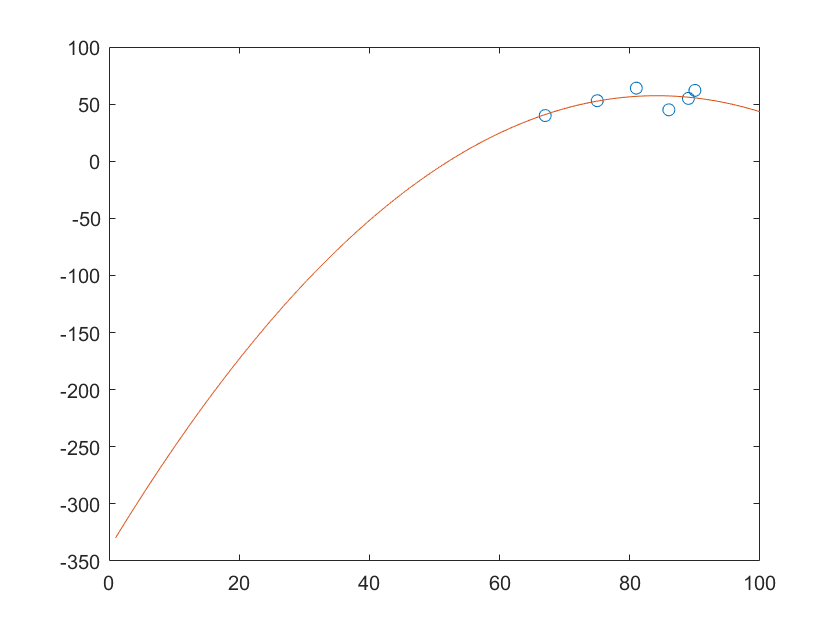

figure (4);
x=[90,86,67,89,81,75];
y=[62,45,40,55,64,53];
V(:,2+1) = ones(length(x),1,class(x));
for j = 2:-1:1
    V(:,j) = x'.*V(:,j+1);
end
res = V\y';
Xi = [1:1:100];
Yi = res(1).*Xi.^2 + res(2).*Xi + res(3); 
plot(x,y,'o'); hold on;
plot(Xi,Yi);hold off;

**g) And computing this fitting **$\mathit{\mathbf{y}}={\mathbf{ax}}^3 +{\mathbf{bx}}^2 +\mathbf{cx}+\mathit{\mathbf{d}}$

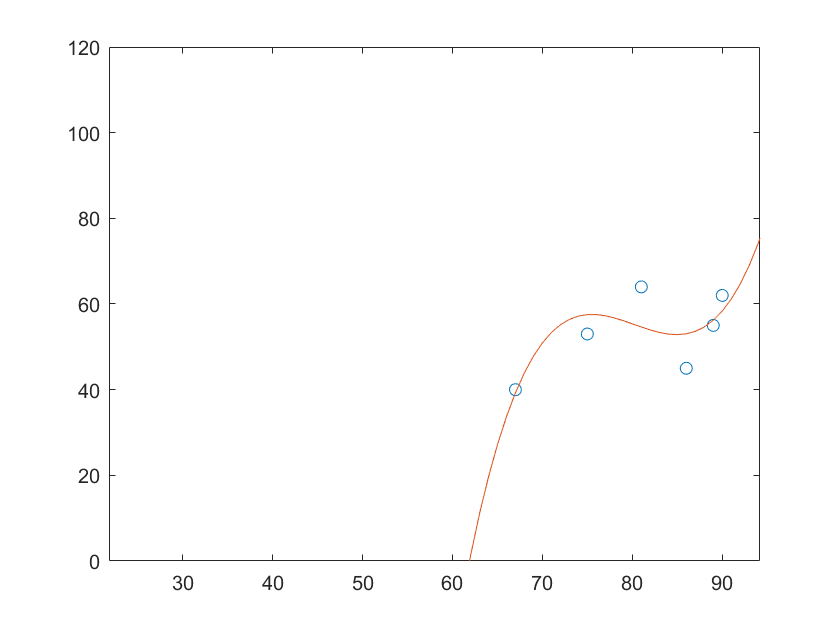

figure (5);
V = [];
V(:,3+1) = ones(length(x),1,class(x));
for j = 3:-1:1
    V(:,j) = x'.*V(:,j+1);
end
res = V\y';
Xi = [1:1:100];
Yi = res(1).*Xi.^3 + res(2).*Xi.^2 + res(3).*Xi+res(4); 
plot(x,y,'o'); hold on;
plot(Xi,Yi);hold off;

xlim([21.8 94.2])
ylim([0 120])

**h) Calculate the operation **$\mathbf{y}=\frac{1}{{\mathbf{y}}^2 }$** to obtain a new vector and compute a new fitting **$\mathit{\mathbf{y}}=\mathit{\mathbf{a}}*{\mathit{\mathbf{e}}}^{\textrm{bx}}$

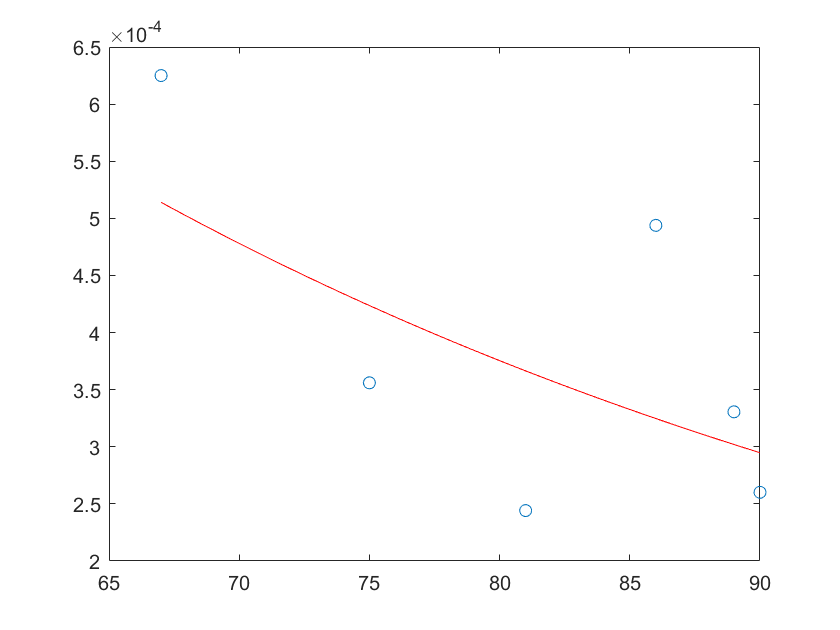

figure (6);
y =1./(y.^2);
y = y';
x = x';
% cambio de variable en los datos
yp=log(y); 
% solucion del problema lineal
A = [x ones(size(x))];
sol = inv(A'*A)*(A'*yp);
B = sol(1); C = sol(2);
% calculamos los parámetros de la exponencial
A=exp(C); 
plot (x,y,'o'); hold on;
xp = linspace(min(x),max(x));
yr = A*exp(B*xp);
plot(xp,yr,'r');
hold off;

**i) Calculate the operation **$\textrm{x2}=\frac{\mathit{\mathbf{x}}}{100}$** ; **$\mathbf{y2}=5*\mathbf{x2}*{\mathbf{e}}^{4\mathbf{x2}}$** and compute a new fitting** $\mathbf{y}=\mathbf{C}*\mathit{\mathbf{x}}*{\mathbf{e}}^{\mathbf{A}\mathbf{x}}$**. What are the values of C and A? Does it seems to C = 5 and A = 4? Why not?**

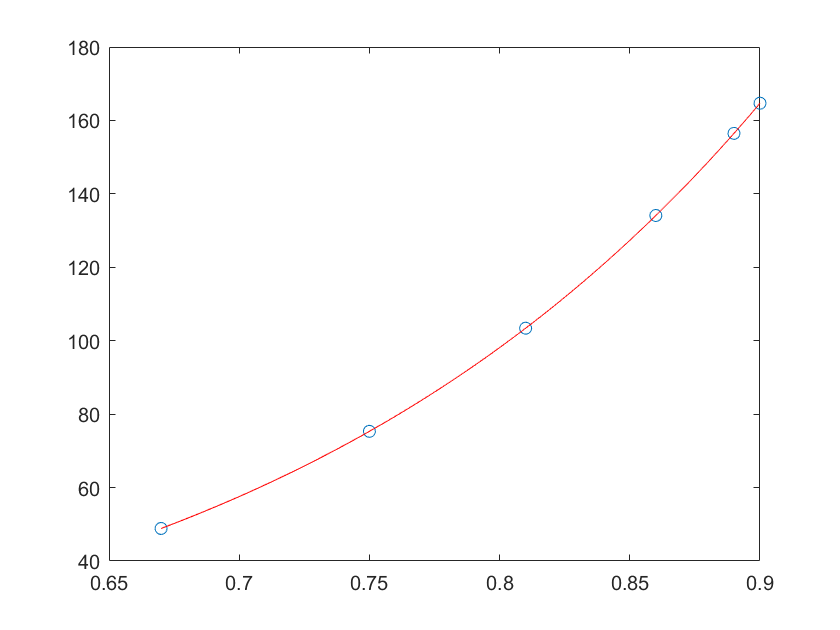

figure (7);
x2 =x/100;
y2 = 5.*x2.*exp(4*x2);
yp =log(y2./x2);

A = [x2 ones(size(x2))];
sol = inv(A'*A)*(A'*yp);
B = sol(1);
C = sol(2);

A = exp(C);
plot(x2,y2,'o');
hold on;

xp = linspace(min(x2),max(x2));
yr = A.*xp.*exp(B*xp);
plot(xp,yr,'r');hold off;

A

A = 5.0000

C

C = 1.6094

# **EXERCISE 2: POLINOMIAL FUNCTION IN MATLAB**

**a) Calculate the paragraphs b), f), g), h) and i) of the previous exercise using the following MATLAB functions:**

- **polyfit: to calculate polynomial coefficients**

- **polyval: to evaluate polynomials**

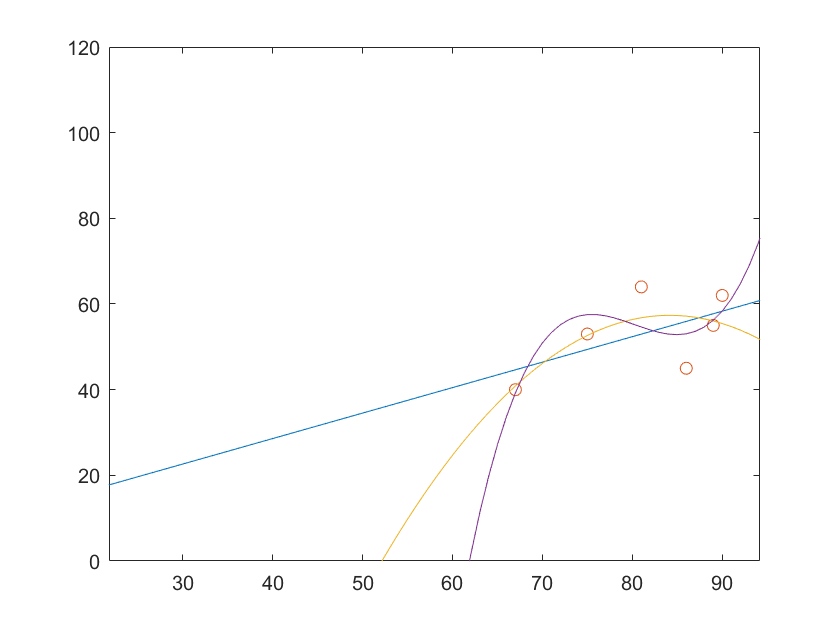

figure(8);
x=[90,86,67,89,81,75];
y=[62,45,40,55,64,53];
coeff = polyfit(x,y,1);
plot(Xi,polyval(coeff,Xi));hold on;
plot(x,y,'o');
coeffF = polyfit(x,y,2);
plot(Xi,polyval(coeffF,Xi));
coeffG = polyfit(x,y,3);
plot(Xi,polyval(coeffG,Xi));hold off;
xlim([21.8 94.2])
ylim([0 120])

figure (9);
y2 = 1./(y.*y);
P = polyfit(x,log(y2),1);

B = P(1);
C = P(2);
A = exp(C);
xr = linspace(min(x),max(x));
yr = A*exp(B*xr);

figure;
plot(x,y2,'o');hold on;
plot(xr,yr,'r');hold off;

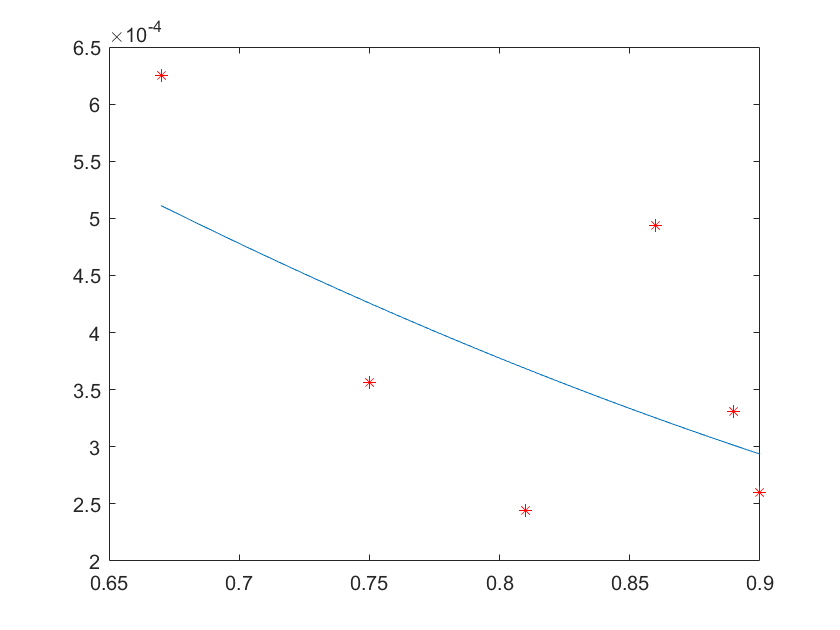

figure
x2 = x2';
b = log(y2./x2);
plot(x2,y2,'r*'); hold on;
p = polyfit(x2,b,1);

xr = linspace(min(x2),max(x2));
yr = polyval(p,xr);
yr = exp(yr);
yr = xr.*yr;
plot(xr,yr); hold off;

**b) Use the function roots to find the polynomial roots in f and g exercises.**

f)

roots(coeffF)

ans =   116.1682
   52.1492


g)

roots(coeffG)

ans =   89.3847 +13.6010i
  89.3847 -13.6010i
  61.8889 + 0.0000i
